% time = [0, 3, 5, 7, 10, 13, 16, 19, 22]
% amp = [0, 0.2, 0.4, 0.6, 0.3, -0.3, -0.3, 0.2, -0.3]

time = [0, 3, 6, 9, 12, 15, 18, 21, 24];

time =      0     3     6     9    12    15    18    21    24


amp = [0, 0.3, -0.3, 0.5, -0.5, 0.6, -0.6, 0.7, -0.7];

amp =          0    0.3000   -0.3000    0.5000   -0.5000    0.6000   -0.6000    0.7000   -0.7000


Na zajęciac z pomocą multimetra zostalo zmierzone napiecie przy wysokich wartosciach sterowania. 

Widac na wykresie ze silnik po jakims czasie wylacza sie (ma przerwy w przeplywie pradu) co skutkuje niedokladnym

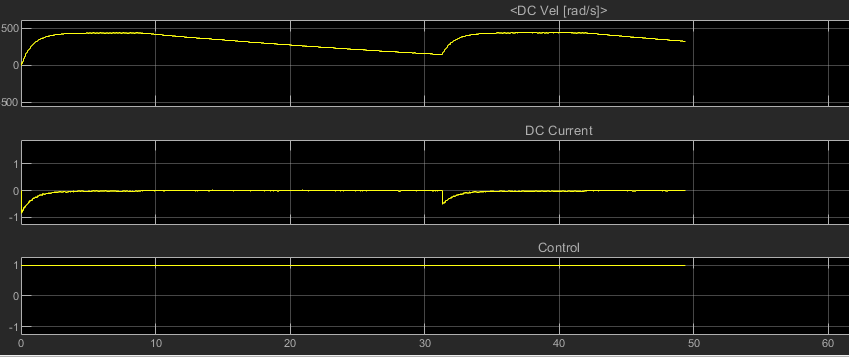

Zauważono rowniez roznice wzgledem multimetra a napiecia (funkcja napiecia od sterowania nie jest lniowa) dlatego zrobiona zostala tabelka napiecia od sterowania pwm

amp = -1:0.1:1;
time = 0:5:100;


Tabelka:

reshape(signal_model_mat(1).values, 1, [])

ans =          0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0005   -0.0005   -0.0003    0.0000    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0003    0.0000   -0.0040   -0.0338   -0.1068   -0.1898   -0.2097   -0.1473   -0.0267    0.0764    0.1172    0.1164    0.1107    0.1043    0.1061    0.1233    0.2693    0.4198    0.4515    0.3317    0.1034   -0.0918   -0.1611   -0.1476   -0.1400   -0.1462   -0.3226   -0.5231   -0.5672   -0.4122   -0.1140    0.1401


Następnie zostal sprawdzony sygnal schodkowy dla duzych wartosci i dziala 

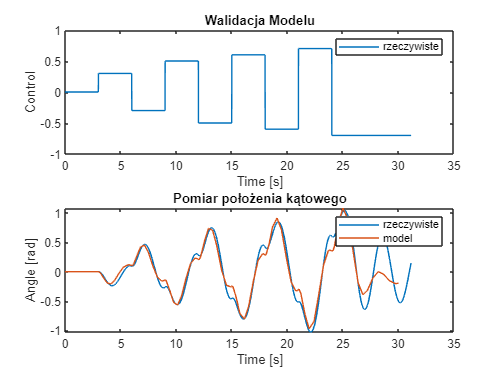

model_rzeczywisty = sygnal_schodkowy_nr1;
signal_model_real = sygnal_schodkowy_nr1.signals;
% sim("src\simulink_models\model_walidacyjny\model_matematyczny_2018a.slx");

model_matematyczny = out.model_matematyczny_nr1;
signal_model_mat = model_matematyczny.signals;

figure;
subplot(2, 1, 1)
plot(model_rzeczywisty.time, signal_model_real(8).values)
xlabel('Time [s]')
legend('rzeczywiste')
ylabel('Control')
title('Walidacja Modelu')

subplot(2, 1, 2)
plot(model_rzeczywisty.time, signal_model_real(1).values)
hold on;
val = reshape(signal_model_mat(1).values, 1, []);
plot(model_matematyczny.time, val)
hold off;
legend('rzeczywiste', 'model')
xlabel('Time [s]')
ylabel('Angle [rad]')
title('Pomiar położenia kątowego')

figure;
subplot(2, 1, 1)
plot(model_rzeczywisty.time, signal_model_real(8).values)
xlabel('Time [s]')
legend('rzeczywiste', 'model')

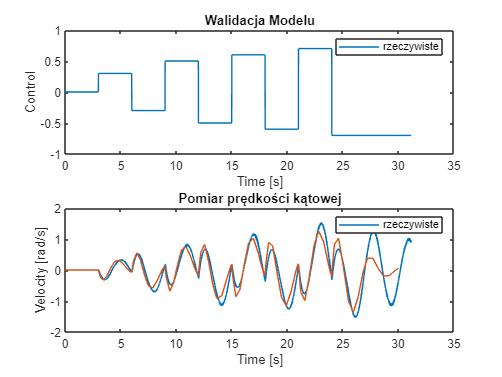

ylabel('Control')
title('Walidacja Modelu')

subplot(2, 1, 2)
plot(model_rzeczywisty.time, signal_model_real(4).values)
hold on;
val = reshape(signal_model_mat(2).values, 1, []);
plot(model_matematyczny.time, val)
hold off;
xlabel('Time [s]')
legend('rzeczywiste')
ylabel('Velocity [rad/s]')
title('Pomiar prędkości kątowej')

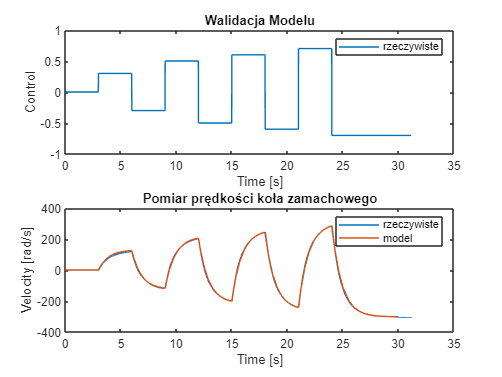

figure;
subplot(2, 1, 1)
plot(model_rzeczywisty.time, signal_model_real(8).values)
xlabel('Time [s]')
legend('rzeczywiste')
ylabel('Control')
title('Walidacja Modelu')

subplot(2, 1, 2)
plot(model_rzeczywisty.time, signal_model_real(6).values)
hold on;
val = reshape(signal_model_mat(3).values, 1, []);
plot(model_matematyczny.time, val)
hold off;
xlabel('Time [s]')
legend('rzeczywiste', 'model')
ylabel('Velocity [rad/s]')
title('Pomiar prędkości koła zamachowego')

Następnie sprawdziliśmy male sterowania -0.1, 0, 0.1 

model_rzeczywisty = sygnal_schodkowy_nr2;

time =      0     3     6     9    12    15    18    21    24    27


amp =          0    0.1000         0   -0.1000         0    0.1000         0   -0.2000         0    0.2000


 Wartośc napięcia zmierzona na silniku w zależności od sterowania:

voltage = [-11.71, -10.69, -9.51, -8.32, -7.13, -5.93, -4.74, -3.55, -2.36, -1.18, 0, 1.61, 2.33, 3.53, 4.69, 5.91, 7.10, 8.27, 9.47, 10.66, 11.75]

voltage =   -11.7100  -10.6900   -9.5100   -8.3200   -7.1300   -5.9300   -4.7400   -3.5500   -2.3600   -1.1800         0    1.6100    2.3300    3.5300    4.6900    5.9100    7.1000    8.2700    9.4700   10.6600   11.7500


u = -1:0.1:1

u =    -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


p_volt = polyfit(u, voltage, 1)

p_volt =    11.8238    0.0095


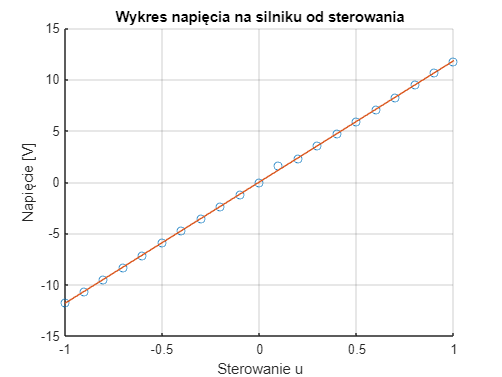

figure
hold on
plot(u, voltage, 'o')
plot(u, polyval(p_volt, u))
hold off
grid on
title('Wykres napięcia na silniku od sterowania')
xlabel('Sterowanie u')
ylabel('Napięcie [V]')